## Eval Metric

evalMetric computes:

- The energy tensor,

- The eulerian energy tensor,

- The null, weak, strong and dominant energy conditions,

- The expansion, shear, and vorticity scalars,

All in 1 line of code.

%% Make Metric
gridSize = [1 20 20 20];
worldCenter = (gridSize+1)./2;
velocity = 0.5;
R = 5;
sigma = 0.5;
Metric = metricGet_AlcubierreComoving(gridSize,worldCenter,velocity,R,sigma);

%% Run evalMetric
[Evaluation] = evalMetric(Metric);

Get field names

fieldnames(Evaluation)

ans = 10×1 cell array
    {'metric'              }
    {'energyTensor'        }
    {'energyTensorEulerian'}
    {'null'                }
    {'weak'                }
    {'strong'              }
    {'dominant'            }
    {'expansion'           }
    {'shear'               }
    {'vorticity'           }


### Metric

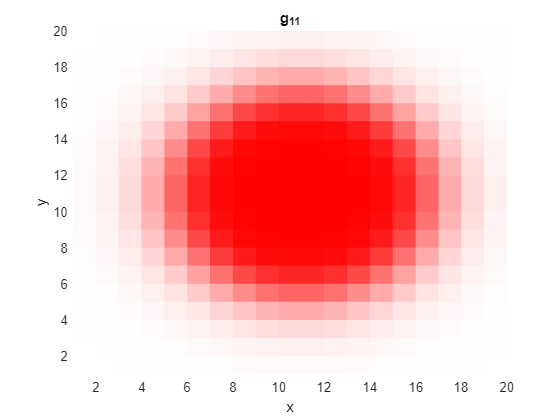

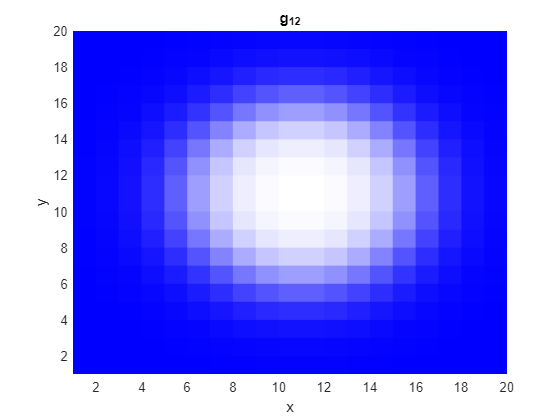

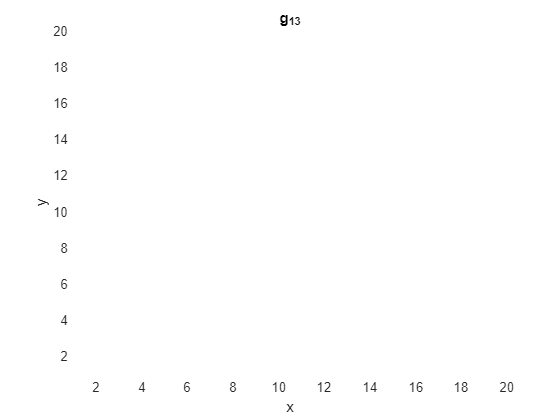

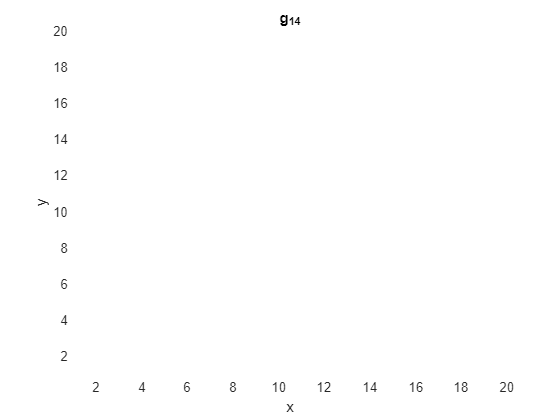

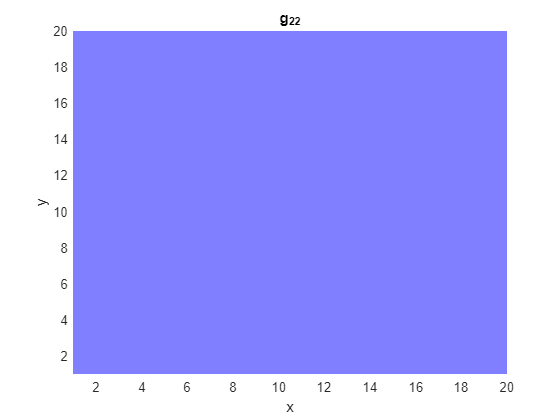

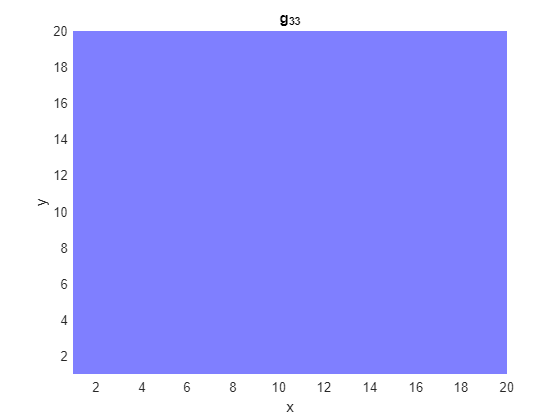

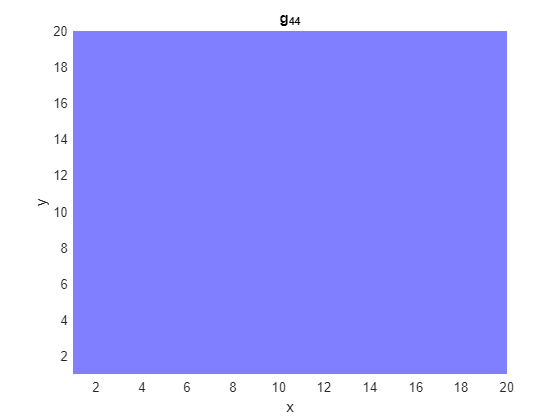

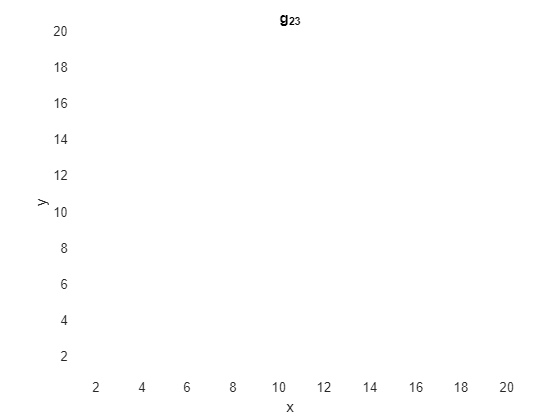

plotTensor(Evaluation.metric, 0)

### Energy Tensor

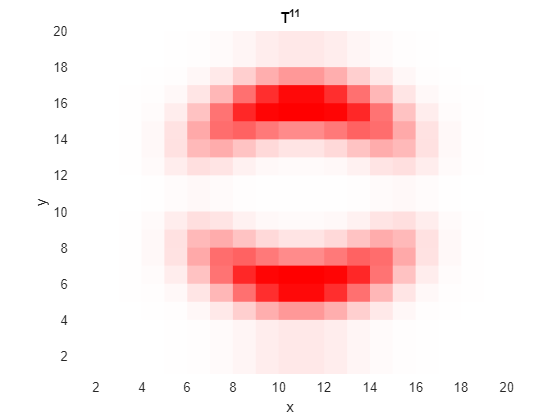

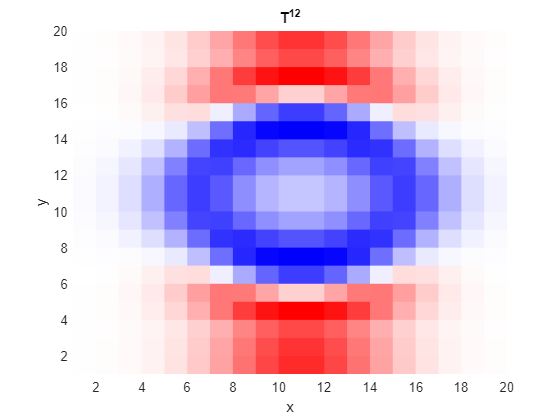

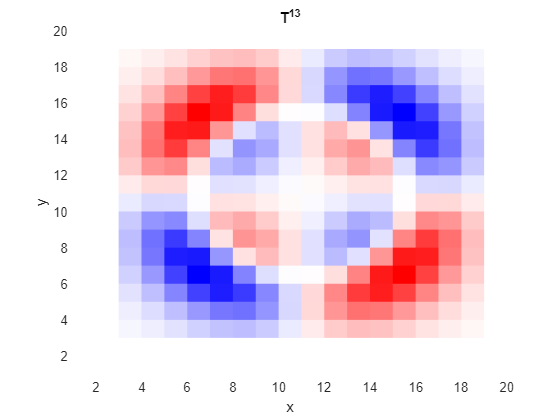

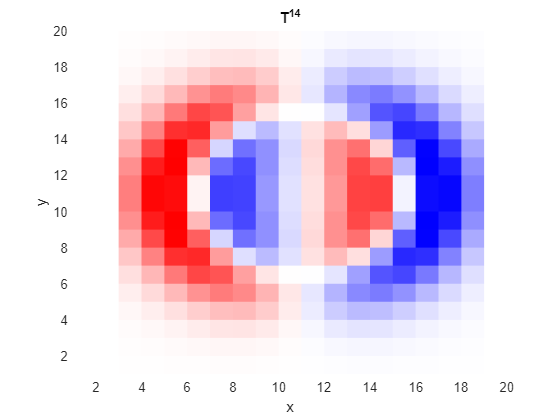

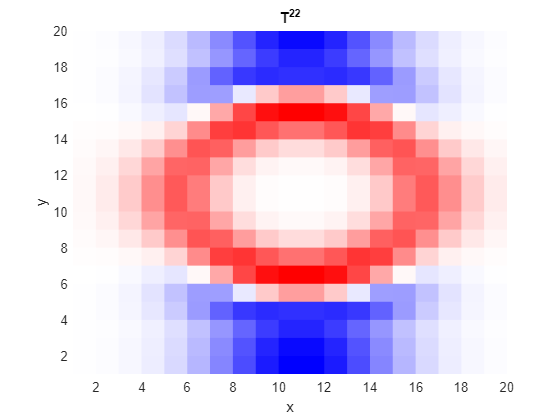

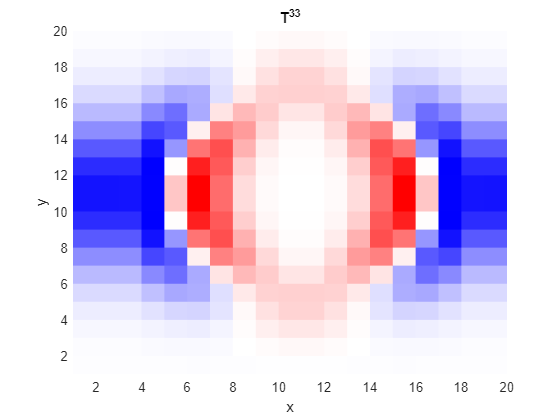

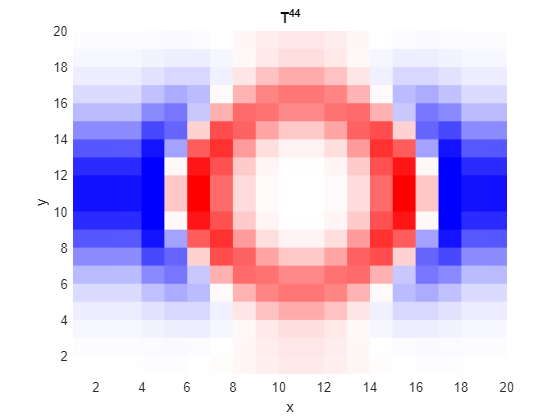

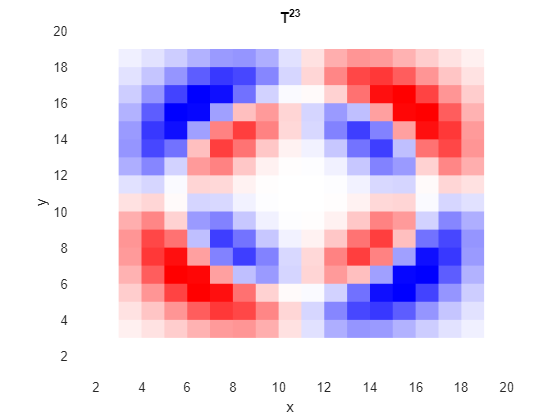

plotTensor(Evaluation.energyTensor, 0)

### Eulerian Energy Tensor

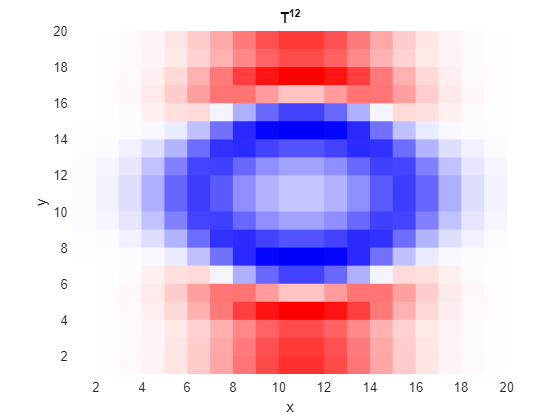

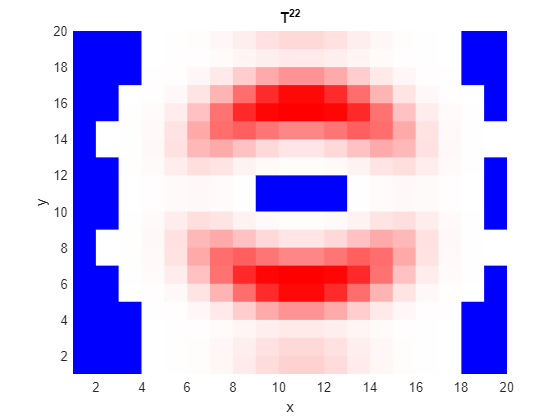

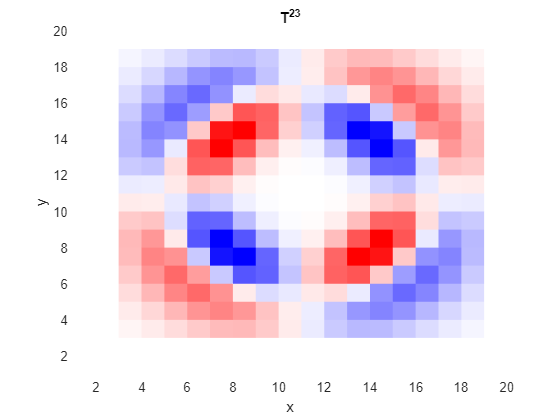

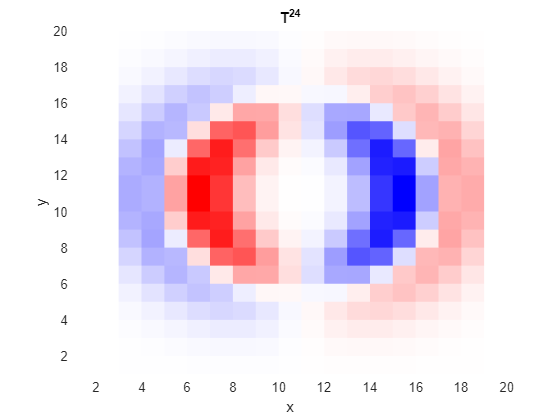

plotTensor(Evaluation.energyTensorEulerian, 0)

### Null Energy Condition

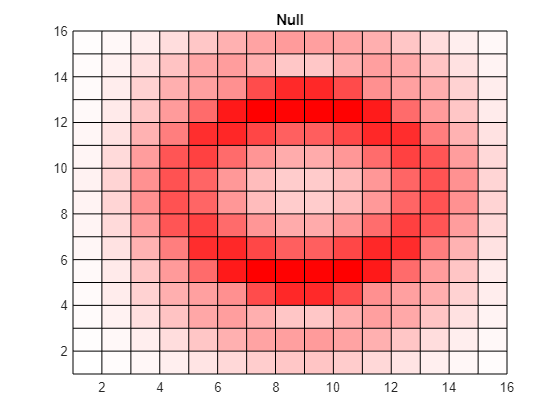

surfq(Evaluation.null(1,3:end-2,3:end-2,round(worldCenter(4))))
title("Null")
view(2)
xlim([1 gridSize(2)-4])
ylim([1 gridSize(3)-4])

### Weak Energy Condition

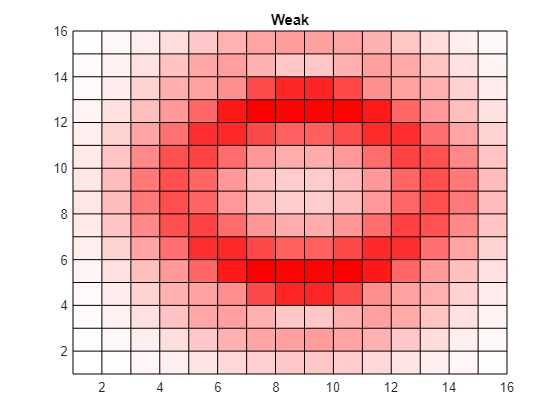

surfq(Evaluation.weak(1,3:end-2,3:end-2,round(worldCenter(4))))
title("Weak")
view(2)
xlim([1 gridSize(2)-4])
ylim([1 gridSize(3)-4])

### Strong Energy Condition

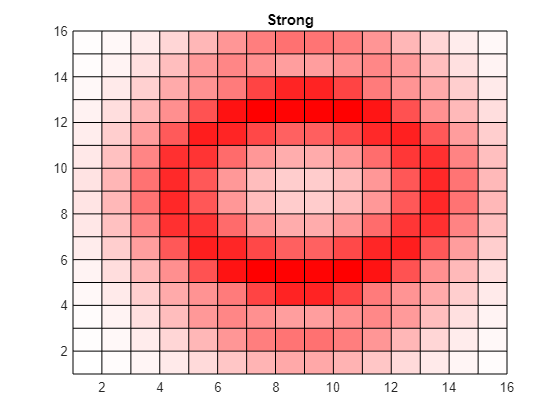

surfq(Evaluation.strong(1,3:end-2,3:end-2,round(worldCenter(4))))
title("Strong")
view(2)
xlim([1 gridSize(2)-4])
ylim([1 gridSize(3)-4])

### Dominant Energy Condition

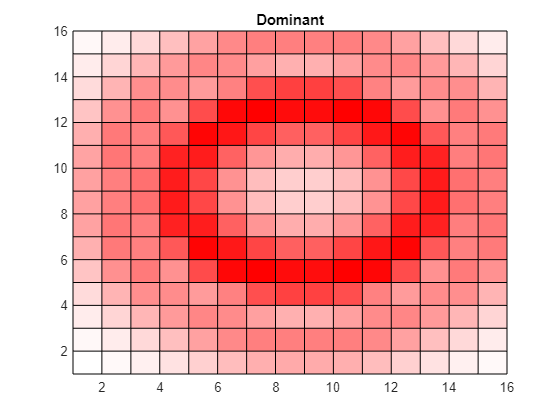

surfq(Evaluation.dominant(1,3:end-2,3:end-2,round(worldCenter(4))))
title("Dominant")
view(2)
xlim([1 gridSize(2)-4])
ylim([1 gridSize(3)-4])

### Expansion Scalar

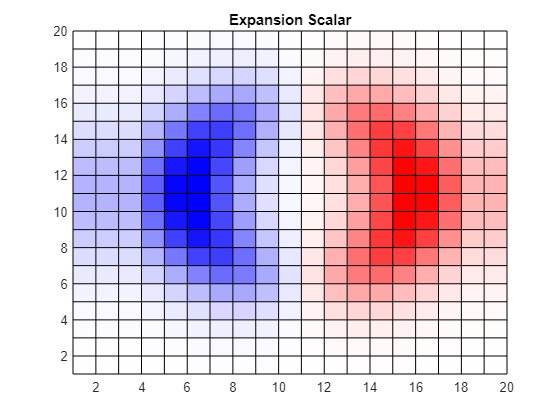

surfq(Evaluation.expansion(1,:,:,round(worldCenter(4))))
title("Expansion Scalar")
view(2)
xlim([1 gridSize(2)])
ylim([1 gridSize(3)])

### Shear Scalar

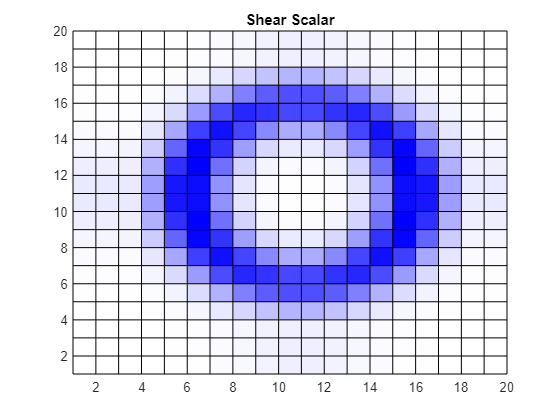

surfq(Evaluation.shear(1,:,:,round(worldCenter(4))))
title("Shear Scalar")
view(2)
xlim([1 gridSize(2)])
ylim([1 gridSize(3)])

### Vorticity Scalar

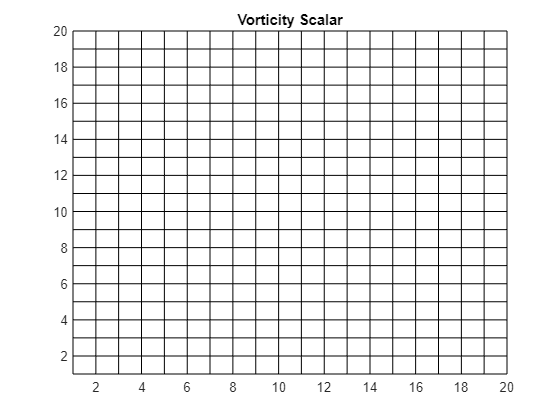

surfq(Evaluation.vorticity(1,:,:,round(worldCenter(4))))
title("Vorticity Scalar")
view(2)
xlim([1 gridSize(2)])
ylim([1 gridSize(3)])

Vorticity should always be 0.